% =========================================================
%  Multi-Layer Perceptron (MLP) trained by Back-Propagation
%
%  Architecture  :  Input -> [Hidden Layer(s)] -> Output
%  Task          :  Binary / Multi-class classification
%                   (demo uses XOR  +  spiral dataset)
%  Activations   :  Sigmoid (hidden),  Softmax (output)
%  Loss          :  Cross-entropy
%  Optimiser     :  Mini-batch SGD with momentum
% =========================================================

clc; clear; close all;

%% ── 1. CONFIGURATION ────────────────────────────────────
cfg.layer_sizes  = [2, 8, 8, 2];   % [input, hidden..., output]
cfg.lr           = 0.05;            % learning rate
cfg.momentum     = 0.9;             % momentum coefficient
cfg.epochs       = 500;             % training epochs
cfg.batch_size   = 16;              % mini-batch size
cfg.lambda       = 1e-4;            % L2 regularisation strength
cfg.val_split    = 0.2;             % fraction held out for validation

%% ── 2. GENERATE SPIRAL DATASET ──────────────────────────
[X, y_raw] = make_spiral(200, 2);   % 200 pts/class, 2 classes
% one-hot encode labels
n_classes = max(y_raw);
Y = full(sparse(1:numel(y_raw), y_raw, 1));   % [N x C]

% Train / Validation split
N   = size(X,1);
idx = randperm(N);
n_val  = round(cfg.val_split * N);
i_val  = idx(1:n_val);
i_trn  = idx(n_val+1:end);

X_trn = X(i_trn,:);  Y_trn = Y(i_trn,:);
X_val = X(i_val,:);  Y_val = Y(i_val,:);
y_val = y_raw(i_val);

%% ── 3. INITIALISE NETWORK (Xavier) ──────────────────────
L      = numel(cfg.layer_sizes);    % total layers including input
net    = init_network(cfg.layer_sizes);
vel    = init_velocity(net);        % momentum buffers

%% ── 4. TRAINING LOOP ────────────────────────────────────
history.trn_loss = zeros(cfg.epochs,1);
history.val_loss = zeros(cfg.epochs,1);
history.val_acc  = zeros(cfg.epochs,1);

n_trn = size(X_trn,1);

for epoch = 1:cfg.epochs
    % --- shuffle training set each epoch
    perm    = randperm(n_trn);
    X_shuf  = X_trn(perm,:);
    Y_shuf  = Y_trn(perm,:);
    epoch_loss = 0;

    % --- mini-batch loop
    for b = 1 : ceil(n_trn / cfg.batch_size)
        b_start = (b-1)*cfg.batch_size + 1;
        b_end   = min(b*cfg.batch_size, n_trn);
        Xb = X_shuf(b_start:b_end, :);
        Yb = Y_shuf(b_start:b_end, :);

        % ── FORWARD PASS ──────────────────────────────
        [cache, loss] = forward(net, Xb, Yb, cfg.lambda);
        epoch_loss    = epoch_loss + loss * (b_end - b_start + 1);

        % ── BACKWARD PASS (back-propagation) ──────────
        grads = backward(net, cache, Xb, Yb, cfg.lambda);

        % ── PARAMETER UPDATE (SGD + momentum) ─────────
        [net, vel] = update_params(net, vel, grads, cfg.lr, cfg.momentum);
    end

    % --- record metrics
    history.trn_loss(epoch) = epoch_loss / n_trn;
    [history.val_loss(epoch), history.val_acc(epoch)] = ...
        evaluate(net, X_val, Y_val, y_val, cfg.lambda);

    if mod(epoch,100)==0
        fprintf('Epoch %3d | trn_loss %.4f | val_loss %.4f | val_acc %.1f%%\n', ...
            epoch, history.trn_loss(epoch), ...
            history.val_loss(epoch), history.val_acc(epoch)*100);
    end
end

Epoch 100 | trn_loss 0.6787 | val_loss 0.6656 | val_acc 61.3%
Epoch 200 | trn_loss 0.6832 | val_loss 0.6647 | val_acc 57.5%
Epoch 300 | trn_loss 0.6809 | val_loss 0.6697 | val_acc 58.8%
Epoch 400 | trn_loss 0.6775 | val_loss 0.6737 | val_acc 56.2%
Epoch 500 | trn_loss 0.6761 | val_loss 0.6762 | val_acc 60.0%


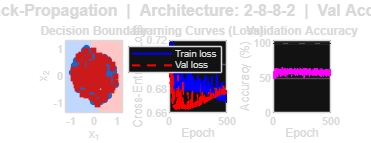


%% ── 5. VISUALISE RESULTS ─────────────────────────────────
plot_results(net, X, y_raw, X_trn, X_val, history, cfg);



% =========================================================
%                   FUNCTION LIBRARY
% =========================================================

%% ── init_network: Xavier weight initialisation ───────────
function net = init_network(sizes)
    L = numel(sizes);
    net.W = cell(L-1,1);
    net.b = cell(L-1,1);
    for l = 1:L-1
        fan_in  = sizes(l);
        fan_out = sizes(l+1);
        % Xavier / Glorot uniform initialisation
        limit   = sqrt(6 / (fan_in + fan_out));
        net.W{l} = (rand(fan_in, fan_out) * 2 - 1) * limit;
        net.b{l} = zeros(1, fan_out);
    end
    net.sizes = sizes;
end

%% ── init_velocity: zero momentum buffers ────────────────
function vel = init_velocity(net)
    L = numel(net.sizes);
    vel.W = cell(L-1,1);
    vel.b = cell(L-1,1);
    for l = 1:L-1
        vel.W{l} = zeros(size(net.W{l}));
        vel.b{l} = zeros(size(net.b{l}));
    end
end

%% ── forward: forward pass + cross-entropy loss ───────────
function [cache, loss] = forward(net, X, Y, lambda)
    % X : [batch x d_in]
    % Y : [batch x n_classes]  (one-hot)
    L   = numel(net.W);
    A   = cell(L+1,1);   % activations (A{1} = input)
    Z   = cell(L,1);     % pre-activations

    A{1} = X;
    for l = 1:L
        Z{l}   = A{l} * net.W{l} + repmat(net.b{l}, size(A{l},1), 1);
        if l < L
            A{l+1} = sigmoid(Z{l});      % hidden layers
        else
            A{l+1} = softmax(Z{l});      % output layer
        end
    end

    % cross-entropy loss  +  L2 regularisation
    batch   = size(X,1);
    eps     = 1e-12;
    ce_loss = -sum(sum(Y .* log(A{L+1} + eps))) / batch;
    l2_loss = 0;
    for l = 1:L
        l2_loss = l2_loss + sum(sum(net.W{l}.^2));
    end
    loss    = ce_loss + 0.5 * lambda * l2_loss;

    % cache everything needed for backward
    cache.A = A;
    cache.Z = Z;
end

%% ── backward: back-propagation ───────────────────────────
function grads = backward(net, cache, X, Y, lambda)
    % Returns gradients grads.dW{l}, grads.db{l}
    L     = numel(net.W);
    batch = size(X,1);
    A     = cache.A;
    Z     = cache.Z;

    dZ    = cell(L,1);
    grads.dW = cell(L,1);
    grads.db = cell(L,1);

    % Output layer delta  (softmax + cross-entropy => A - Y)
    dZ{L} = (A{L+1} - Y) / batch;

    % Hidden layer deltas (back-propagate)
    for l = L-1 : -1 : 1
        dA      = dZ{l+1} * net.W{l+1}';
        dZ{l}   = dA .* sigmoid_deriv(Z{l});
    end

    % Compute gradients for weights and biases
    for l = 1:L
        grads.dW{l} = A{l}' * dZ{l} + lambda * net.W{l};  % + L2 grad
        grads.db{l} = sum(dZ{l}, 1);
    end
end

%% ── update_params: SGD with momentum ────────────────────
function [net, vel] = update_params(net, vel, grads, lr, mu)
    L = numel(net.W);
    for l = 1:L
        vel.W{l} = mu * vel.W{l} - lr * grads.dW{l};
        vel.b{l} = mu * vel.b{l} - lr * grads.db{l};
        net.W{l} = net.W{l} + vel.W{l};
        net.b{l} = net.b{l} + vel.b{l};
    end
end

%% ── evaluate: loss + accuracy on a dataset ──────────────
function [loss, acc] = evaluate(net, X, Y, y_true, lambda)
    [cache, loss] = forward(net, X, Y, lambda);
    L       = numel(net.W);
    probs   = cache.A{L+1};
    [~, y_pred] = max(probs, [], 2);
    acc     = mean(y_pred == y_true);
end

%% ── predict: return class labels ────────────────────────
function y_pred = predict(net, X)
    L   = numel(net.W);
    A   = X;
    for l = 1:L
        Z = A * net.W{l} + repmat(net.b{l}, size(A,1), 1);
        if l < L
            A = sigmoid(Z);
        else
            A = softmax(Z);
        end
    end
    [~, y_pred] = max(A, [], 2);
end

%% ── Activation functions ────────────────────────────────
function a = sigmoid(z)
    a = 1 ./ (1 + exp(-z));
end

function d = sigmoid_deriv(z)
    s = sigmoid(z);
    d = s .* (1 - s);
end

function a = softmax(z)
    % numerically stable: subtract row max
    z  = z - max(z, [], 2);
    e  = exp(z);
    a  = e ./ sum(e, 2);
end

%% ── make_spiral: 2-D spiral dataset ─────────────────────
function [X, y] = make_spiral(n_per_class, n_classes)
    X = zeros(n_per_class * n_classes, 2);
    y = zeros(n_per_class * n_classes, 1);
    for c = 1:n_classes
        ix    = (c-1)*n_per_class + 1 : c*n_per_class;
        t     = linspace(0.1, 1, n_per_class)';
        theta = t * 4 * pi + (c-1) * (2*pi/n_classes);
        r     = t;
        X(ix,:) = [r .* sin(theta) + 0.05*randn(n_per_class,1), ...
                   r .* cos(theta) + 0.05*randn(n_per_class,1)];
        y(ix)   = c;
    end
    perm = randperm(n_per_class * n_classes);
    X = X(perm,:);
    y = y(perm);
end

%% ── plot_results ─────────────────────────────────────────
function plot_results(net, X, y, X_trn, X_val, history, cfg)
    figure('Name','MLP Back-Propagation', ...
           'Color','white','Position',[80 80 1300 500]);

    % --- (a) Decision surface ---
    subplot(1,3,1);
    h = 0.03;
    x1r = min(X(:,1))-0.3 : h : max(X(:,1))+0.3;
    x2r = min(X(:,2))-0.3 : h : max(X(:,2))+0.3;
    [G1,G2] = meshgrid(x1r, x2r);
    Xg      = [G1(:), G2(:)];
    yg      = predict(net, Xg);
    Yg      = reshape(yg, size(G1));

    cmap = [0.75 0.85 1.0; 1.0 0.78 0.78];
    imagesc(x1r, x2r, Yg); colormap(cmap);
    set(gca,'YDir','normal'); hold on;

    colors = [0.1 0.4 0.8; 0.8 0.1 0.1];
    markers = {'o','s'};
    for c = 1:2
        plot(X_trn(y(ismember(X,X_trn,'rows'))==c, 1), ...
             X_trn(y(ismember(X,X_trn,'rows'))==c, 2), ...
             markers{c}, 'Color', colors(c,:), ...
             'MarkerFaceColor', colors(c,:), 'MarkerSize', 5);
    end
    xlabel('x_1'); ylabel('x_2');
    title('Decision Boundary');
    axis tight; box on;

    % --- (b) Loss curves ---
    subplot(1,3,2);
    ep = 1:cfg.epochs;
    plot(ep, history.trn_loss, 'b-',  'LineWidth',1.5, 'DisplayName','Train loss');
    hold on;
    plot(ep, history.val_loss, 'r--', 'LineWidth',1.5, 'DisplayName','Val loss');
    xlabel('Epoch'); ylabel('Cross-Entropy Loss');
    title('Learning Curves (Loss)');
    legend('Location','northeast'); grid on;

    % --- (c) Validation accuracy ---
    subplot(1,3,3);
    plot(ep, history.val_acc * 100, 'm-', 'LineWidth',1.5);
    xlabel('Epoch'); ylabel('Accuracy (%)');
    title('Validation Accuracy');
    ylim([0 105]); grid on;
    yline(100,'k--','LineWidth',0.8);

    final_acc = history.val_acc(end)*100;
    sgtitle(sprintf('MLP Back-Propagation  |  Architecture: %s  |  Val Acc: %.1f%%', ...
        strjoin(arrayfun(@num2str,cfg.layer_sizes,'UniformOutput',false),'-'), ...
        final_acc), 'FontSize',12,'FontWeight','bold');
end